clc;
clear all;
close all;

## generate data

run ("Basics.m")

sys =
 
                 1.3 s + 1.333
  --------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



fb = 2.4327

sysd =
 
  0.0004236 z^3 + 0.001167 z^2 - 0.000997 z - 0.0003069
  -----------------------------------------------------
      z^4 - 3.481 z^3 + 4.58 z^2 - 2.697 z + 0.5991
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



c =          0    0.0004    0.0012   -0.0010   -0.0003


d =     1.0000   -3.4807    4.5802   -2.6968    0.5991


tfinal=200;
t = 0:T_s:tfinal;
u = zeros(numel(t),1);

#### General Input+white Noise

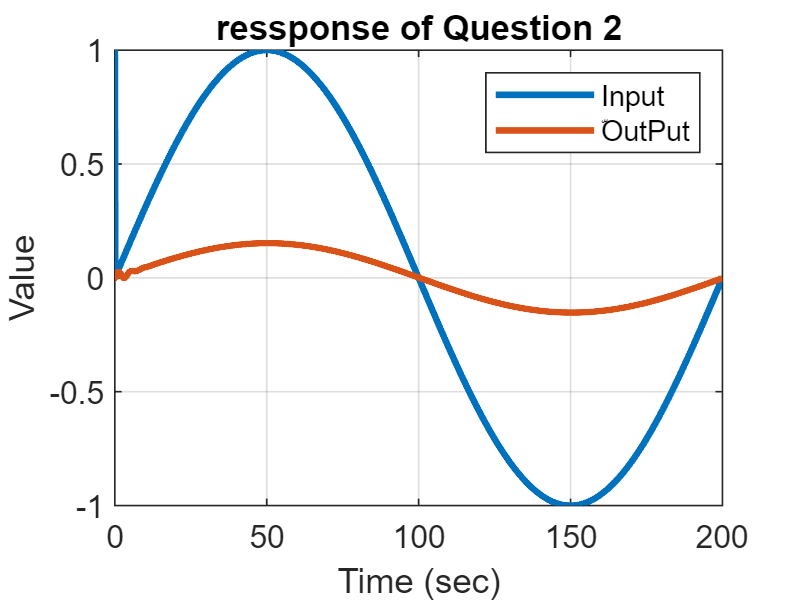

u = gensig('sine' , tfinal , tfinal ,T_s)+gensig('pulse' , tfinal , tfinal ,T_s);
% Noise=-0.2+(0.2+0.2)*rand(numel(t),1)/2;
% u=u+Noise;
y = lsim(sysd  ,u ,t);
plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;

## recursive least esquare estimation

N = numel(y) ;
%choose number of parameters
Parameters_in_den=4

Parameters_in_den = 4

Parameters_in_num=4

Parameters_in_num = 4

Nv=Parameters_in_num+Parameters_in_den

Nv = 8

theta(:,1:Nv) =3*ones(Nv , Nv) ;
P = eye(Nv) ;
phi=[];


for i = (max(Parameters_in_num,Parameters_in_den)+1):N
    phi(:,i) = [(y(i-1:-1:i-Parameters_in_den))' , (u(i-1:-1:i-Parameters_in_num))']';
    P=(P+phi(:,i)'*phi(:,i))^(-1);
    erorr=y(i) - phi(:,i)'*theta(:,i-1);
    theta(:,i) = theta(:,i-1) + P*phi(:,i)*(erorr); 
end


### ‌BODE

ident_dis = tf(theta((Parameters_in_num+1):end,end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s)

ident_dis =
 
   0.1338 z^3 + 0.2665 z^2 + 0.3992 z - 2.559
  ---------------------------------------------
  z^4 - 3.076 z^3 - 3.097 z^2 - 3.116 z - 3.132
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
     -4.455 s^4 + 160.7 s^3 - 3646 s^2 + 5.06e04 s - 1.577e05
  --------------------------------------------------------------
  s^5 - 7.955 s^4 + 721.9 s^3 - 7231 s^2 + 8.374e04 s - 1.024e06
 
Continuous-time transfer function.



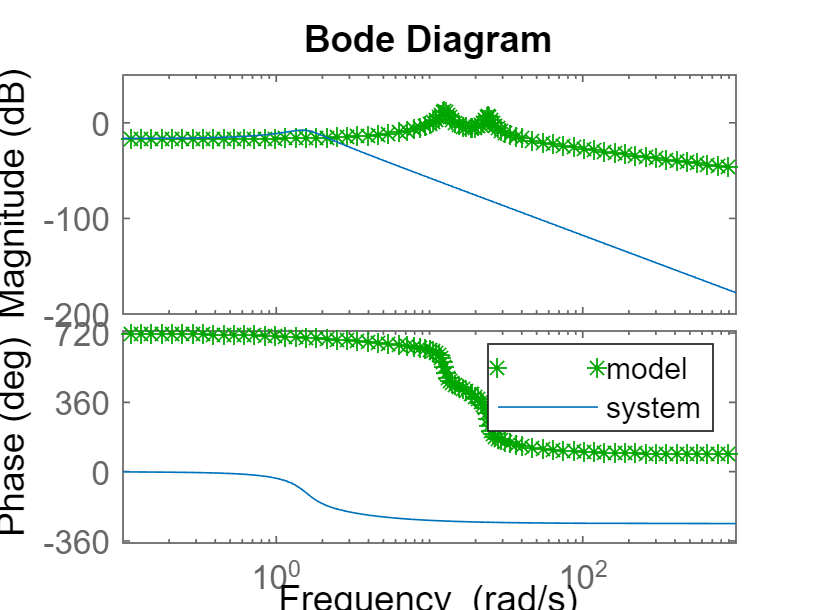

bode(ident_analog ,'g*',sys)
legend('model ','system')

RLS Convergence

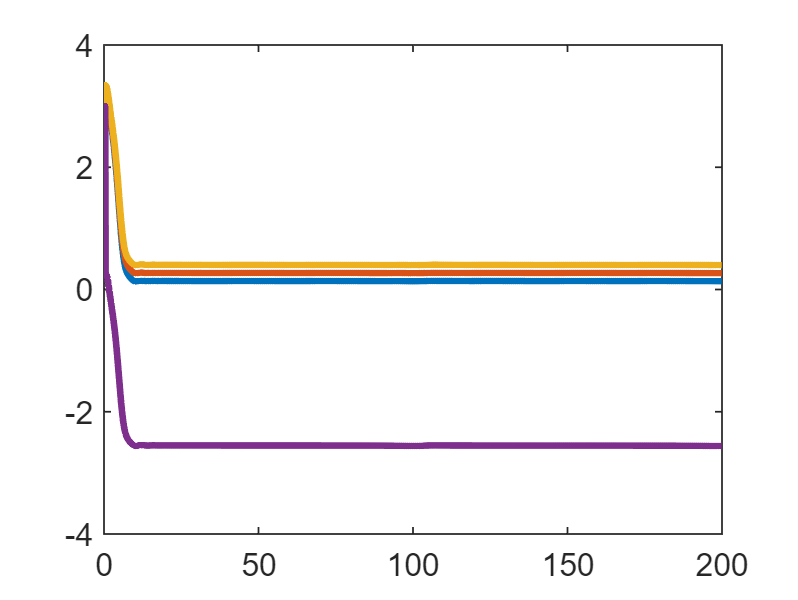

% subplot(2,1,1)
plot(t , theta((Parameters_in_num+1):end,:) , 'LineWidth' , 2) ;

% xlabel('Time (sec)') ;
% ylabel('Parameters') ;
% title('RLS convergence Num') ;
% grid on
% legend('a_1','a_2','a_3','a_4')
% % xlim([0 6])
% % ylim([-0.5 0.5])
% %--------------------------------------------------------------
% subplot(2,1,2)
% plot(t , -theta(1:Parameters_in_num ,:) , 'LineWidth' , 2) ;
% xlabel('Time (sec)') ;
% ylabel('Parameters') ;
% title('RLS convergence Den') ;
% grid on
% legend('b_1','b_2','b_3','b_4')
% % xlim([0 6])
% % ylim([-2 2])

### Ploting discret system and Least square Model via step input

% figure
% step(sysd,0:T_s:100*T_s)
% hold on
% step(ident_analog,0:T_s:100*T_s,'r+')
% legend('\fontsize{12} discret system','\fontsize{12} Ls Model');
% grid on;
% xlabel('time','fontsize',12);

% % figure
% % plot(Eror)
% % xlabel('Iteration') ;
% % ylabel('error square') ;
% % title('Cost function \times 2') ;
% % 
% % toc
